# **1D concentration profile from a reconstructed APT tip**

**Voxelisation of atom probe data in 1D, calculating concentrations, creating 1D concentration profiles**

In order to calculate a 1D concentration profile, the APT tip needs to be already reconstructed, and therefore the mass spectrum has to be ranged and the pos file parsed (so that a ion variable (column name) is generated). These steps can be found in the live script **FirstSteps**.

## Creation of grid vectors

The function *binVectorsFromDistance* creates a set of grid vectors to be used in nD binning (here for one dimension). First, the distance variable needs to be specified, in which the binning will be performed. If no particular ROI is wanted, the typical distance is represented by the z axis of the pos variable.

dist = pos.z % determine the distance variable to be binned

dist =     3.8349
    3.3057
    6.9697
    3.6701
    3.1982
    2.2917
    3.1592
    4.0918
    3.8535
    6.2615


There are **two modes** possible. Choose the wanted case and comment the unwanted case in this live script in order to execute the live script properly since the input variables *bin* and *mode* are practically 'connected' (for the mode *'distance'*  values between 1 and around 20 make sense, whereas the mode *'count'* needs much higher values).

**Case #1:** *'distance'* is used as *mode*, which resembles the distance in nm from bin edge to bin edge

bin = 3.5 % bin width in nm

bin = 3.5000

mode = 'distance'

mode = 'distance'

[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode) % creates bin centers and bin edges of the voxels

binCenters = 1×1 cell array
    {1×70 double}


binEdges = 1×1 cell array
    {1×71 double}


**Case #2:** *'count'* is used as *mode*, which resembles the number of counts, which are present between two consecutive bin edges

% bin = 390000 % number of counts within each bin
% mode = 'count'
% [binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode) % creates bin centers and bin edges of the voxels
 

## Voxelisation of the data set

In the next step, the voxelisation will be performed based on the bin edges. This means in 1D, that the reconstructed APT tip is separated into slices of the size determined in the previous step. 

Each slice exhibits either a specified thickness in nm (for mode *'distance'*) or consists of a certain number of counts (for mode *'count'*). As a side note, be aware that the final slice most likely is thinner or contains less atoms compared to the other slices. This is only logical and relates to the way the slices are created.

vox = posNdBin(pos, dist, binEdges) % creates a cell array of various pos subsets, representing the voxelisation of the pos variable

vox = 70×1 cell array
    { 13075×7 table}
    {103692×7 table}
    {166809×7 table}
    {173972×7 table}
    {177503×7 table}
    {183172×7 table}
    {189562×7 table}
    {194055×7 table}
    {200701×7 table}
    {205498×7 table}
    {209906×7 table}
    {214588×7 table}
    {218881×7 table}
    {225796×7 table}
    {229191×7 table}
    {237147×7 table}


## Creation of an anonymous function

In the next step, a so-called anonymous function will be defined. This means that a variable will be created, which is a function. By doing so, the subsequent step can be executed more easily.

As input, the detector efficiency is needed. For example, in case of the LEAP 4000X HR, this value is 0.37 or 37 %, respectively.

The inputs *excludeList* and *volumeName* are optional:

detEff = 37 % detector efficiency, input as decimal or percentage figure possible

detEff = 37

excludeList = {'Ga' 'unranged'} % insert ions which should be excluded from the list, 'unranged' is also possible, optional

excludeList = 1×2 cell array
    {'Ga'}    {'unranged'}


volumeName = '' % name of the volumes, parsed as character array, optional


volumeName =

  0×0 empty char array



ck = @(pos) posCalculateConcentrationSimple(pos, detEff, excludeList, volumeName)

ck = function_handle with value:
    @(pos)posCalculateConcentrationSimple(pos,detEff,excludeList,volumeName)


## Plotting of a 1D concentration profile

In order to plot a 1D concentration profile, it is necessary to execute following function so that the calculated concentration values correspond to a distance value.

conc1D = binApplyConcentrationFunction(vox, binCenters, ck, {'nm'})

conc1D = 210×14 table
      volume       distance    type        format            C             C2            C3            D             Fe            H             Mn           O H2           Si        unranged
    ___________    ________    _____    _____________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ________

    <undefined>         0      ionic    count                   180            47            40            22        

Now, to visualise the concentration profile, only the concentration values need to be plotted over the distance.

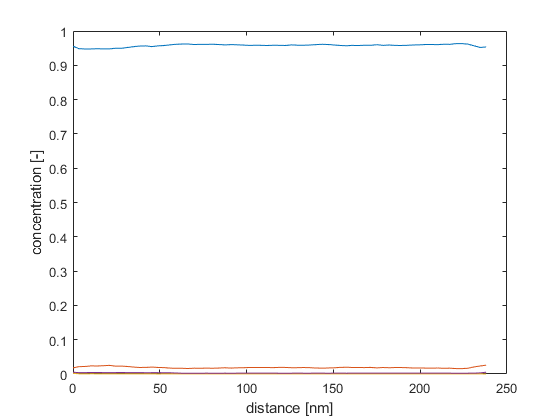

data = conc1D(conc1D.format == 'concentration',:); % creates a table only with rows of 'concentration'
figure; % creates new figure
pl = plot( ...                                    % plots the concentration profile for all input species
    data.distance, data.Fe, ... % enter element symbol (e.g. Fe) or complex ion (e.g. ("O H2") 
    data.distance, data.C, ... % if you want to plot more/fewer elements, add/delete line(s)
    data.distance, data.D, ... % NOTE: the last line must end with a parenthesis 
    data.distance, data.H);          
xlabel('distance [nm]'); % inserts label on x axis
ylabel('concentration [-]'); % inserts label on y axis

## Calculation of concentrations for each voxel

With the ntext function, the user can extract the concentration values of all ranged ions, except the elements of the *excludeList*, for each voxel.

conc = cellfun(ck, vox, 'UniformOutput', false) % performs the function 'ck' on each element of the cell array 'vox'
 

## Extraction of concentration values for a specific species

In order to access the concentration values for a specific species, following function can be used. Just enter the wanted element or complex ion name. The output is a column vector with values representing the concentration (as a fraction) of the wanted species for each voxel.

concWantedSpecies = cellfun(@(x) x. (x.format == 'concentration'), conc) % enter element symbol (e.g. Fe) or complex ion (e.g. ("O H2")

concWantedSpecies =     0.0051
    0.0040
    0.0041
    0.0043
    0.0045
    0.0041
    0.0040
    0.0042
    0.0044
    0.0041
